# 公式推导

## 定义

本教程以 5 物种、6 反应为例：

- **物种浓度向量 **$$\mathbf{y}$$：维度为 $$nSp \times 1$$（列向量）。


$$$$\mathbf{y} = \left[ \begin{array}{c} y_1 \\ y_2 \\ \vdots \\ y_{nSp} \end{array} \right] = \left[ \begin{array}{c} [\mathrm{ONE}] \\ [\mathrm{RO}_2] \\ [\mathrm{A}] \\ [\mathrm{B}] \\ [\mathrm{C}] \end{array} \right]$$$$


- **反应速率向量 **$$\mathbf{R}$$：维度为 $$nRx \times 1$$（列向量），记录每个反应的瞬时速率。

- **化学计量系数矩阵**$ $\mathbf{f}$$：维度为 $$nRx \times nSp$$。其中 $$f_{ij}$ $表示**第 **$$i$$** 个反应中物种 **$$j$$** 的净变化系数**（消耗为负，生成为正）。

## 微分状态方程

对于任意一个物种 $$j$$，它的浓度随时间的变化率（即 $$d y_j / dt$$）是由**所有参与了该物种的反应速率加权累加**决定的：


$$$$\frac{d y_j}{dt} = \sum_{i=1}^{nRx} f_{ij} R_i$$$$


如果将所有物种的微分方程组合起来，写成整体的列向量形式 $$\frac{d\mathbf{y}}{dt}$$，利用矩阵乘法的物理定义，可以极其优雅地写成：


$$$$\frac{d\mathbf{y}}{dt} = \mathbf{f}^T \cdot \mathbf{R}$$$$


**注意维度对齐**：$$\mathbf{f}^T$$ 的维度是 $$nSp \times nRx$$，$$\mathbf{R}$$ 的维度是 $$nRx \times 1$$，相乘后正好得到 $$nSp \times 1$$ 的列向向量。这对应了代码中 dydt = rates' * f 的转置实现。

## 雅可比矩阵的组装

雅可比矩阵 $$\mathbf{J}$$ 是**微分状态方程对各个状态变量（物种浓度）的偏导数方阵**，其维度为 $$nSp \times nSp$$。它是**物种对物种**的方阵。 它的**每一行代表受到波及的物种 **$$j$$**，每一列代表主动挑事的物种 **$$k$$（物种 k 变动，对第 $$i$$ 个反应的速率会产生多大的催化或抑制作用？）。

矩阵中的第 $$j$$ 行、第 $$k$$ 列的元素 $$J_{jk}$$ 定义为：


$$$$J_{jk} = \frac{\partial}{\partial y_k} \left( \frac{d y_j}{dt} \right)$$$$


这一项的物理意义是：**当物种 **$$k$$** 的浓度发生微小变化时，物种 **$$j$$** 的净生成速率会受到多大的影响。**

我们将状态方程代入定义中：


$$$$J_{jk} = \frac{\partial}{\partial y_k} \left( \sum_{i=1}^{nRx} f_{ij} R_i \right)$$$$


由于化学计量系数 $$f_{ij}$$ 是常数（不由浓度决定），根据导数的线性性质，可以把偏导数移入求和号内部：


$$$$J_{jk} = \sum_{i=1}^{nRx} f_{ij} \frac{\partial R_i}{\partial y_k}$$$$


这是一个典型的矩阵乘法形式。如果我们定义一个**速率偏导矩阵 **$$\mathbf{DrDy}$$（在化学中常称为偏导通量矩阵），其维度为 $$nRx \times nSp$$，元素为：


$$$$\text{DrDy}_{ik} = \frac{\partial R_i}{\partial y_k}$$$$


那么，上述求和公式在矩阵层面上就可以完美地展开为：


$$$$\mathbf{J} = \mathbf{f}^T \cdot \mathbf{DrDy}$$$$


我们切入到矩阵内部看一个具体的交点 —— $$J_{A, B}$$**（第 3 行，第 4 列）**：


$$$$J_{A, B} = \frac{\partial}{\partial y_B} \left( \frac{dy_A}{dt} \right)$$$$


它代表：**如果空气中自由基 **$$B$$** 增加，物种 **$$A$$** 的死活会受到什么影响？**

通过矩阵乘法：


$$$$J_{A, B} = \sum_{i=1}^6 (\text{反应 } i \text{ 对 } A \text{ 的化学计量数}) \times (\text{反应 } i \text{ 对物种 } B \text{ 的灵敏度})$$$$


- **扫描 Rx ①**：Rx ① 消耗 $$A$$（计量数 $$-1$$），且 Rx ① 对 $$B$$ 很敏感（灵敏度 $$k_1 y_A$$）。相乘得到：$$-1 \times k_1 y_A$$。

- **扫描 Rx ④**：Rx ④ 对 $$B$$ 也很敏感（灵敏度 $$2k_4 y_B$$），但是 Rx ④ 根本不关 $$A$$ 的事（计量数 $$0$$）。相乘得到：$$0 \times 2k_4 y_B = 0$$。

- **其余反应**：均不平衡或不相关，相乘均为 $$0$$。

最终在这个网络的 $$(A, B)$$ 交叉点上，算出来的结果就是：


$$$$J_{A, B} = -k_1 y_A$$$$


这就非常符合直观的物理：$$B$$** 越多，反应①就被催化得越快；而反应①是杀灭 **$$A$$** 的，所以 **$$B$$** 越多，**$$A$$** 消失得就越快！**

## $$\mathbf{DrDy}$$ 内部的多元乘积微分规则

在 F0AM 框架下，任何反应 $$i$$ 的速率公式都由 iG 矩阵参数化为三项相乘：


$$$$R_i = k_i \cdot y_{g_1} \cdot y_{g_2} \cdot y_{g_3}$$$$


*(其中 *$$g_1, g_2, g_3$$* 分别为反应物在 **iG(i,:)** 中的物种索引)*

为了计算 $$\frac{\partial R_i}{\partial y_k}$$，我们需要对该乘积应用数学中的**多元函数乘 Product Rule（多元乘积微分法则）**：


$$$$\frac{\partial R_i}{\partial y_k} = k_i \left( \frac{\partial y_{g_1}}{\partial y_k} y_{g_2} y_{g_3} + y_{g_1} \frac{\partial y_{g_2}}{\partial y_k} y_{g_3} + y_{g_1} y_{g_2} \frac{\partial y_{g_3}}{\partial y_k} \right)$$$$


由于状态变量之间相互独立，偏导数满足克罗内克函数（Kronecker delta）性质：


$$$$\frac{\partial y_m}{\partial y_k} = \begin{cases} 1, & \text{if } m = k \\ 0, & \text{if } m \neq k \end{cases}$$$$


## **实例演算演示**

我们用机理中的两个代表性反应来做物理还原：

**情况 A：常规二级反应（如 反应①: **$$A + B \rightarrow C + B$$**）**

该反应速率为 $$R_1 = k_1 \cdot y_A \cdot y_B \cdot 1$$（这里 $$y_{\text{ONE}}=1$$）。

- 对物种 $$A$$ 求偏导：$$\frac{\partial R_1}{\partial y_A} = k_1 \cdot 1 \cdot y_B \cdot 1 = k_1 y_B$$

- 对物种 $$B$$ 求偏导：$$\frac{\partial R_1}{\partial y_B} = k_1 \cdot y_A \cdot 1 \cdot 1 = k_1 y_A$$

- 对其他不相干物种（如 $$C$$）求偏导：$$\frac{\partial R_1}{\partial y_C} = 0$$

**情况 B：同种自由基自反应（如 反应④: **$$B + B \rightarrow \text{loss}$$**）**

该反应速率为 $$R_4 = k_4 \cdot y_B \cdot y_B \cdot 1 = k_4 y_B^2$$。

根据一元求导法则，我们熟知 $$\frac{\partial R_4}{\partial y_B} = 2 k_4 y_B$$。

如果带入我们底层的多元微分代码逻辑中：

- 当 $$s = B$$ 时：

- 第一项 $$$g_1 = B \Rightarrow$$$ 贡献 $$y_B \cdot 1 = y_B$$

- 第二项 $$g_2 = B  \Rightarrow$$ 贡献 $$y_B \cdot 1 = y_B$$

- 第三项 $$g_3 = \text{ONE} \neq B  \Rightarrow$$ 贡献$ $0$$

- 相加得到：$$k_4 \cdot (y_B + y_B) = 2 k_4 y_B$$。

这证明了底层的隐式遍历求导代码具有严格的**数学自洽性**，能够完美兼容大气化学中复杂的自反应、三体反应等特殊动力学情景。

## 为什么解析推导对 `ode15s` 至关重要？

如果没有这个数学推导，MATLAB 的 ode15s 将默认采用**数值差分（Finite Difference）** 笨办法来逼近雅可比矩阵：


$$$$J_{jk} \approx \frac{\frac{dy_j}{dt}(y_k + \Delta y_k) - \frac{dy_j}{dt}(y_k)}{\Delta y_k}$$$$


这意味着，系统每往前走一步，求解器为了探测斜率，必须把整个大机制的 dydt 重新扰动调用 $$nSp$$ 次！当机制包含上千个物种时，传统的数值差分会带来指数级的算力灾难。而有了上述推导出的 $$\mathbf{J} = \mathbf{f}^T \cdot \mathbf{DrDy}$$，我们只需执行一次**稀疏矩阵点乘**，就能在毫秒内精确吐出矩阵结果，这就是 F0AM 能够高效运行的数学底气。

## 问题的引出：隐式代数方程

假设我们的化学反应动力学系统方程为：


$$$$\frac{d\mathbf{y}}{dt} = \mathbf{F}(\mathbf{y})$$$$


*(其中 *$$\mathbf{F}(\mathbf{y}) = \mathbf{f}^T \cdot \mathbf{R}$$*，即所有物种的瞬时净变化率。或者写成：*$$\mathbf{F}(\mathbf{y}_{n+1}, \mathbf{y}_n)$$*，只要右手边有 *$$\mathbf{y}_{n+1}$$*，它就是****隐式，****参考以下几种高级隐式变体)*

如果使用最简单的显式算法，下一步的浓度 $$\mathbf{y}_{n+1}$$ 很容易算。但面对刚性方程（比如某些自由基寿命极短，导致 $$\mathbf{F}(\mathbf{y})$$ 变化剧烈），显式算法会瞬间崩溃。因此，求解器必须采用**隐式欧拉法**：


$$$$\mathbf{y}_{n+1} = \mathbf{y}_n + \Delta t \cdot \mathbf{F}(\mathbf{y}_{n+1})$$$$


**核心难点：** 注意等号右边是 $$\mathbf{F}(\mathbf{y}_{n+1})$$！我们要求的未知数 $$\mathbf{y}_{n+1}$$ 被深深地锁在了复杂的非线性化学速率方程 $$\mathbf{F}$$ 内部。这在数学上变成了一个**非线性方程组求根问题**。

为了求解，我们定义一个残差函数（Residual Function）$$\mathbf{G}(\mathbf{y}_{n+1})$$，我们的目标是找到一个完美的 $$\mathbf{y}_{n+1}$$ 让残差归零：


$$$$\mathbf{G}(\mathbf{y}_{n+1}) = \mathbf{y}_{n+1} - \mathbf{y}_n - \Delta t \cdot \mathbf{F}(\mathbf{y}_{n+1}) = \mathbf{0}$$$$


## 牛顿-拉夫森迭代（Newton-Raphson Iteration）与雅可比矩阵

解这个大型非线性方程组 $$\mathbf{G} = \mathbf{0}$$，最有效的数学武器就是**牛顿迭代法**。

假设我们在当前时间步内进行第 $$m$$ 次逼近，当前的近似解为 $$\mathbf{y}_{n+1}^{(m)}$$。我们将 $$\mathbf{G}(\mathbf{y}_{n+1})$$ 在 $$\mathbf{y}_{n+1}^{(m)}$$ 处进行**一阶泰勒展开**以线性化逼近：


$$$$\mathbf{G}(\mathbf{y}_{n+1}^{(m)} + \Delta \mathbf{y}^{(m)}) \approx \mathbf{G}(\mathbf{y}_{n+1}^{(m)}) + \frac{\partial \mathbf{G}}{\partial \mathbf{y}} \cdot \Delta \mathbf{y}^{(m)} = \mathbf{0}$$$$


这里的 $$\frac{\partial \mathbf{G}}{\partial \mathbf{y}}$$ 就是**残差函数的雅可比矩阵**。我们根据定义对 $$\mathbf{G}$$ 求偏导：


$$$$\frac{\partial \mathbf{G}}{\partial \mathbf{y}} = \frac{\partial}{\partial \mathbf{y}} \left( \mathbf{y}_{n+1} - \mathbf{y}_n - \Delta t \cdot \mathbf{F}(\mathbf{y}_{n+1}) \right)$$$$


因为 $$\mathbf{y}_n$$ 是上一时刻的常数，且 $$\frac{\partial \mathbf{y}}{\partial \mathbf{y}} = \mathbf{I}$$（单位矩阵），而 $$\frac{\partial \mathbf{F}}{\partial \mathbf{y}}$$ 恰好就是我们拼装的**化学解析雅可比矩阵 **$$\mathbf{J}$$！


$$$$\frac{\partial \mathbf{G}}{\partial \mathbf{y}} = \mathbf{I} - \Delta t \cdot \mathbf{J}$$$$


在数值计算中，这个矩阵被称为**迭代矩阵（Iteration Matrix）**，通常记为 $$\mathbf{W}$$：


$$$$\mathbf{W} = \mathbf{I} - \Delta t \cdot \mathbf{J}$$$$


将迭代矩阵 $$\mathbf{W}$$ 代入泰勒展开式中，我们得到了求解器在底层每一步都在疯狂计算的**核心线性方程组**：


$$$$(\mathbf{I} - \Delta t \cdot \mathbf{J}) \cdot \Delta \mathbf{y}^{(m)} = - \mathbf{G}(\mathbf{y}_{n+1}^{(m)})$$$$


解出修正量 $$\Delta \mathbf{y}^{(m)}$$ 之后，更新当前步的浓度估计值：


$$$$\mathbf{y}_{n+1}^{(m+1)} = \mathbf{y}_{n+1}^{(m)} + \Delta \mathbf{y}^{(m)}$$$$


求解器会一直重复这个迭代过程，直到修正量 $$\Delta \mathbf{y}^{(m)}$$ 小于你设置的容忍度（如 RelTol 和 AbsTol），才算真正跨过了这一个时间步。

## ode15s (BDF 格式)

实际的 ode15s 采用的是比隐式欧拉更高级的**齿轮法 / 后向微分公式（BDF, Backward Differentiation Formulas）**。为了支持变步长和变阶数，它的残差方程形式会引入一个权重系数 $$\gamma$$：


$$$$\mathbf{W} = \mathbf{I} - \gamma \Delta t \cdot \mathbf{J}$$$$


此时底层的线性方程组泛化为：


$$$$\left( \mathbf{I} - \gamma \Delta t \cdot \mathbf{J} \right) \cdot \Delta \mathbf{y}^{(m)} = - \mathbf{G}(\mathbf{y}_{n+1}^{(m)})$$$$


- $$\gamma$$ 是一个由当前算法阶数（1 到 5 阶动态切换）决定的标量常数。

- $$\Delta t$$ 是当前的时间步长。

- $$\mathbf{J}$$ 就是我们推导出的解析雅可比矩阵 $$\mathbf{f}^T \cdot \mathbf{DrDy}$$。

### **显隐式混合方法 (IMEX - Implicit-Explicit Schemes)**：

在某些复杂的大气模型中，物理过程（如扩散、对流）和化学过程（速率方程）是混在一起的。为了省算力，科学家会将 $$\mathbf{F}$$ 拆成两部分：


$$$$\mathbf{F} = \mathbf{F}_{\text{explicit}}(\mathbf{y}_n) + \mathbf{F}_{\text{implicit}}(\mathbf{y}_{n+1})$$$$


写成整体函数的形式，就是$$\mathbf{F}(\mathbf{y}_{n+1}, \mathbf{y}_n)$$。

### **克兰克-尼科尔森方法 (Crank-Nicolson / 梯形公式)**：

它是最著名的混合形式，两边各取一半权重：


$$$$\mathbf{y}_{n+1} = \mathbf{y}_n + \Delta t \cdot \left[ \frac{1}{2}\mathbf{F}(\mathbf{y}_n) + \frac{1}{2}\mathbf{F}(\mathbf{y}_{n+1}) \right]$$$$


它通常具有二阶时空精度。

# F0AM ODE 组装与求解 — 逐步可视化教程

本脚本用 5 个物种、6 个反应的微型机理，展示 F0AM 核心的 ODE 组装 → 稀疏矩阵 → 雅可比矩阵 → ode15s 求解 全过程。

可以在 MATLAB 中用"实时编辑器 (Live Editor)"打开本文件: 编辑器选项卡 → 另存为 → 保存类型: Live Code Files (.mlx) 或者直接在当前编辑器中使用"运行节"功能逐段执行。

clear; close all; clc;
fprintf('===== F0AM ODE 求解器可视化教程 =====\n\n')

===== F0AM ODE 求解器可视化教程 =====



## 步骤 1：定义微型化学机理

% 物种列表 (nSp = 5)
Cnames = {'ONE'    % 占位物种，浓度恒为 1 (用于一级反应)
           'RO2'   % 有机过氧自由基总量 (占位)
           'A'     % 反应物 (类似 VOC)
           'B'     % 自由基 (类似 OH)
           'C'};   % 稳定产物

nSp = length(Cnames);
fprintf('物种 (%d 个):\n', nSp);

物种 (5 个):


for i = 1:nSp
    fprintf('  %2d: %s\n', i, Cnames{i});
end

   1: ONE
   2: RO2
   3: A
   4: B
   5: C



% 反应列表 (nRx = 6)
Rnames = {'A + B  → C + B'   % ① 催化氧化: A 被 B 氧化为 C，B 再生
           'B      → (loss)'  % ② 自由基终止
           'A      → (loss)'  % ③ A 光解损失
           'B + B  → (loss)'  % ④ B 自反应
           '→ A'              % ⑤ A 的排放 (零级)
           'C      → (loss)'};% ⑥ C 沉降损失

nRx = length(Rnames);
fprintf('\n反应 (%d 个):\n', nRx);


反应 (6 个):


for i = 1:nRx
    fprintf('  %2d: %s\n', i, Rnames{i});
end

   1: A + B  → C + B
   2: B      → (loss)
   3: A      → (loss)
   4: B + B  → (loss)
   5: → A
   6: C      → (loss)



% 速率常数 (1/s 或 1/(molec·cm³·s) 取决于反应级数)
% 这里简化，直接给数值
k_values = [1e-3   % k₁: A + B → C + B
            0.01   % k₂: B → loss
            1e-4   % k₃: A → loss
            0.1    % k₄: B + B → loss
            0.5    % k₅: → A  (排放速率)
            1e-4]; % k₆: C → loss

fprintf('\n速率常数:\n');


速率常数:


for i = 1:nRx
    fprintf('  k%d = %.4g\n', i, k_values(i));
end

  k1 = 0.001
  k2 = 0.01
  k3 = 0.0001
  k4 = 0.1
  k5 = 0.5
  k6 = 0.0001


**任意级数 n 的速率常数 ****k****的通用单位公式**为：


$$$$\mathbf{(\text{mol} \cdot \text{L}^{-1})^{1-n} \cdot \text{s}^{-1}} \quad \text{或} \quad \mathbf{\text{mol}^{1-n} \cdot \text{L}^{n-1} \cdot \text{s}^{-1}}$$$$


*(注：时间单位不一定是秒 *$$\text{s}$$*，也可以是分*$ $\text{min}$$* 或小时 *$$\text{h}$$*)*

## 步骤 2：构建核心数据结构 — iG 和稀疏矩阵 f

% 这是 F0AM 最关键的一步：将化学反应翻译成数值矩阵。
%
% iG (nRx × 3): 每个反应的 1~3 个反应物在 Cnames 中的索引
%   G(irxn) = conc(iG(irxn,1)) × conc(iG(irxn,2)) × conc(iG(irxn,3))
%   对于一级反应，用 ONE 填充多余的索引 (conc(ONE)=1)
%
% f (nRx × nSp): 稀疏化学计量系数矩阵
%   f(irxn, isp) = 反应 irxn 中物种 isp 的净化学计量系数
%   (负 = 消耗，正 = 生成)

% ---- 构建 iG ----
% 思路：每种反应需要 1~3 个反应物的乘积
% ONE 的索引 = 1，浓度恒为 1

iONE = 1;  % ONE 总是列表第一个物种

iG = zeros(nRx, 3);

% 反应 1: A + B → C + B   (二级反应: [A][B])
iG(1,:) = [3, 4, iONE];   % = [A, B, ONE] → G = [A]·[B]·1

% 反应 2: B → loss        (一级反应: [B])
iG(2,:) = [4, iONE, iONE]; % = [B, ONE, ONE] → G = [B]·1·1

% 反应 3: A → loss        (一级反应: [A])
iG(3,:) = [3, iONE, iONE]; % = [A, ONE, ONE]

% 反应 4: B + B → loss    (二级反应: [B]²)
iG(4,:) = [4, 4, iONE];    % = [B, B, ONE] → G = [B]·[B]·1

% 反应 5: → A             (零级反应: 1)
iG(5,:) = [iONE, iONE, iONE]; % G = 1·1·1 = 1

% 反应 6: C → loss        (一级反应: [C])
iG(6,:) = [5, iONE, iONE]; % = [C, ONE, ONE]

fprintf('\niG 矩阵 (nRx × 3): 每个反应的 1~3 个反应物索引\n');


iG 矩阵 (nRx × 3): 每个反应的 1~3 个反应物索引


T_iG = table(iG(:,1), iG(:,2), iG(:,3), ...
    'VariableNames', {'idx1','idx2','idx3'}, ...
    'RowNames', strrep(Rnames, '→', '->'));
disp(T_iG);

                        idx1    idx2    idx3
                        ____    ____    ____

    A + B  -> C + B      3       4       1  
    B      -> (loss)     4       1       1  
    A      -> (loss)     3       1       1  
    B + B  -> (loss)     4       4       1  
    -> A                 1       1       1  
    C      -> (loss)     5       1       1  




% ---- 构建稀疏矩阵 f ----
% 用 full 矩阵先演示，再转为 sparse

f_full = zeros(nRx, nSp);

% 反应 1: A + B → C + B  (A:-1, C:+1, B: net 0)
f_full(1, 3) = -1;  % A consumed
f_full(1, 5) = +1;  % C produced
% B: net 0 (consumed 1, produced 1)

% 反应 2: B → loss
f_full(2, 4) = -1;

% 反应 3: A → loss
f_full(3, 3) = -1;

% 反应 4: B + B → loss
f_full(4, 4) = -2;  % 2 B consumed

% 反应 5: → A
f_full(5, 3) = +1;  % A produced

% 反应 6: C → loss
f_full(6, 5) = -1;

% 转换为稀疏矩阵 (F0AM 实际使用的格式)
f_sparse = sparse(f_full);

fprintf('\n\n化学计量矩阵 f (nRx × nSp) — 行=反应, 列=物种:\n');



化学计量矩阵 f (nRx × nSp) — 行=反应, 列=物种:


T_f = array2table(f_full, ...
    'VariableNames', Cnames, ...
    'RowNames', strrep(Rnames, '→', '->'));
disp(T_f);

                        ONE    RO2    A     B     C 
                        ___    ___    __    __    __

    A + B  -> C + B      0      0     -1     0     1
    B      -> (loss)     0      0      0    -1     0
    A      -> (loss)     0      0     -1     0     0
    B + B  -> (loss)     0      0      0    -2     0
    -> A                 0      0      1     0     0
    C      -> (loss)     0      0      0     0    -1



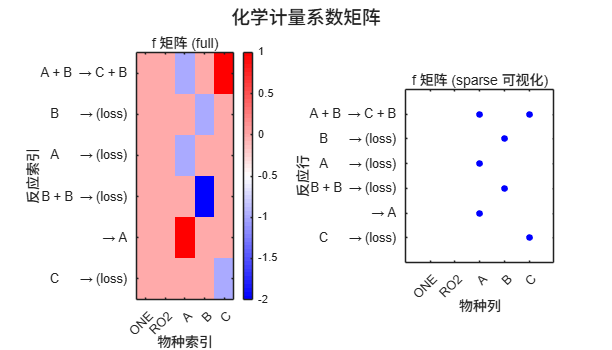


% ---- 可视化 f 矩阵 ----
figure('Position', [100, 100, 700, 400]);

subplot(1,2,1);
imagesc(f_full);
colormap(redbluecm);
colorbar;
title('f 矩阵 (full)');
xlabel('物种索引'); ylabel('反应索引');
set(gca, 'XTick', 1:nSp, 'XTickLabel', Cnames, ...
    'YTick', 1:nRx, 'YTickLabel', Rnames, 'YTickLabelRotation', 0);
xtickangle(45);

subplot(1,2,2);
spy(f_sparse, 'b', 15);
title('f 矩阵 (sparse 可视化)');
xlabel('物种列'); ylabel('反应行');
set(gca, 'XTick', 1:nSp, 'XTickLabel', Cnames, ...
    'YTick', 1:nRx, 'YTickLabel', Rnames);
xtickangle(45);
sgtitle('化学计量系数矩阵', 'FontSize', 14);

## 步骤 3：dydt 求导 — 核心计算

% 给定当前浓度向量 conc (molec/cm³)，计算 dydt
% 这是 ODE 求解器每步都调用的核心函数
%
% 三个步骤:
%   ① G  = conc(iG₁) · conc(iG₂) · conc(iG₃)  (每个反应的"浓度积")
%   ② rates = k · G                             (每个反应的反应速率)
%   ③ dydt = rates · f                          (所有反应对每个物种的净变化之和)
%
% ★ f 是 sparse → 矩阵乘法极快，即使 20000 反应 × 7000 物种

fprintf('\n\n===== dydt 求导计算演示 =====\n');



===== dydt 求导计算演示 =====



% 假设当前时刻的浓度 (ppb)
conc_ppb = [1;      % ONE: 恒为 1
            0;      % RO2: 暂为 0
            100;    % A: 100 ppb
            0.05;   % B: 0.05 ppb
            0];     % C: 0 ppb

fprintf('\n当前浓度 (ppb):\n');


当前浓度 (ppb):


for i = 1:nSp
    fprintf('  %-6s = %.4g ppb\n', Cnames{i}, conc_ppb(i));
end

  ONE    = 1 ppb
  RO2    = 0 ppb
  A      = 100 ppb
  B      = 0.05 ppb
  C      = 0 ppb



% F0AM 内部使用 molec/cm³，但这里为了简单直接使用 ppb 展示计算过程
% 因为 G 的乘积性质在两种单位下原理相同

% 步骤 ①: 计算 G (每个反应的浓度积)
G = zeros(nRx, 1);
for i = 1:nRx
    G(i) = conc_ppb(iG(i,1)) * conc_ppb(iG(i,2)) * conc_ppb(iG(i,3));
end

fprintf('\n步骤①: G(irxn) = conc(iG₁) × conc(iG₂) × conc(iG₃)\n');


步骤①: G(irxn) = conc(iG₁) × conc(iG₂) × conc(iG₃)


for i = 1:nRx
    fprintf('  G%d (%s) = %s × %s × %s = %.4g\n', ...
        i, Rnames{i}, ...
        Cnames{iG(i,1)}, Cnames{iG(i,2)}, Cnames{iG(i,3)}, G(i));
end

  G1 (A + B  → C + B) = A × B × ONE = 5
  G2 (B      → (loss)) = B × ONE × ONE = 0.05
  G3 (A      → (loss)) = A × ONE × ONE = 100
  G4 (B + B  → (loss)) = B × B × ONE = 0.0025
  G5 (→ A) = ONE × ONE × ONE = 1
  G6 (C      → (loss)) = C × ONE × ONE = 0



% 步骤 ②: 计算反应速率
rates = k_values(:) .* G;

fprintf('\n步骤②: rates = k × G\n');


步骤②: rates = k × G


for i = 1:nRx
    fprintf('  rate%d (%s) = %.4g × %.4g = %.4g\n', ...
        i, Rnames{i}, k_values(i), G(i), rates(i));
end

  rate1 (A + B  → C + B) = 0.001 × 5 = 0.005
  rate2 (B      → (loss)) = 0.01 × 0.05 = 0.0005
  rate3 (A      → (loss)) = 0.0001 × 100 = 0.01
  rate4 (B + B  → (loss)) = 0.1 × 0.0025 = 0.00025
  rate5 (→ A) = 0.5 × 1 = 0.5
  rate6 (C      → (loss)) = 0.0001 × 0 = 0



% 步骤 ③: dydt = rates · f  (矩阵乘法)
dydt = rates' * f_full;  % 1 × nSp

fprintf('\n步骤③: dydt = rates^T · f   (关键一步!)\n');


步骤③: dydt = rates^T · f   (关键一步!)


fprintf('  对每个物种: dydt(isp) = Σ(rate(irxn) × f(irxn, isp))\n\n');

  对每个物种: dydt(isp) = Σ(rate(irxn) × f(irxn, isp))



for j = 1:nSp
    contrib = '';
    total = 0;
    for i = 1:nRx
        if f_full(i,j) ~= 0
            val = rates(i) * f_full(i,j);
            total = total + val;
            contrib = [contrib sprintf(' + %.4g × (%+d)', rates(i), f_full(i,j))];
        end
    end
    fprintf('  d[%s]/dt = %s = %.4g ppb/s\n', Cnames{j}, contrib, total);
end

  d[ONE]/dt =  = 0 ppb/s
  d[RO2]/dt =  = 0 ppb/s
  d[A]/dt =  + 0.005 × (-1) + 0.01 × (-1) + 0.5 × (+1) = 0.485 ppb/s
  d[B]/dt =  + 0.0005 × (-1) + 0.00025 × (-2) = -0.001 ppb/s
  d[C]/dt =  + 0.005 × (+1) + 0 × (-1) = 0.005 ppb/s


## 步骤 4：可视化 Jacobian 矩阵

% F0AM 提供解析 Jacobian → 求解速度快 10~100 倍
%
% 对于反应 k·A·B:
%   ∂(k·A·B)/∂A = k·B
%   ∂(k·A·B)/∂B = k·A
%
% 矩阵形式: J = f' · (∂rates/∂conc)
%   其中 ∂rates/∂conc 是稀疏的 nRx × nSp 矩阵
%
% 最终 J 是 nSp × nSp 的方阵

fprintf('\n\n===== Jacobian 矩阵 (解析) =====\n');



===== Jacobian 矩阵 (解析) =====



% 计算 ∂rates/∂conc (每个反应对每个物种的偏导)
DrDy = zeros(nRx, nSp);

% for i = 1:nRx
%     % 对第 1 个反应物求偏导:  ∂(k·c₁·c₂·c₃)/∂c₁ = k·c₂·c₃
%     DrDy(i, iG(i,1)) = k_values(i) * conc_ppb(iG(i,2)) * conc_ppb(iG(i,3));
% 
%     % 对第 2 个反应物求偏导:  ∂(k·c₁·c₂·c₃)/∂c₂ = k·c₁·c₃
%     DrDy(i, iG(i,2)) = DrDy(i, iG(i,2)) + k_values(i) * conc_ppb(iG(i,1)) * conc_ppb(iG(i,3));
% 
%     % 对第 3 个反应物求偏导:  ∂(k·c₁·c₂·c₃)/∂c₃ = k·c₁·c₂
%     DrDy(i, iG(i,3)) = DrDy(i, iG(i,3)) + k_values(i) * conc_ppb(iG(i,1)) * conc_ppb(iG(i,2));
% 
%     % 处理自反应 (B+B): ∂(k·B²)/∂B = 2k·B
%     if iG(i,1) == iG(i,2) && iG(i,1) ~= iONE
%         DrDy(i, iG(i,1)) = 2 * k_values(i) * conc_ppb(iG(i,1));
%     end
% end
for i = 1:nRx
    % 提前提取当前反应的三个反应物索引和浓度
    idx1 = iG(i,1); idx2 = iG(i,2); idx3 = iG(i,3);
    c1 = conc_ppb(idx1); c2 = conc_ppb(idx2); c3 = conc_ppb(idx3);
    k = k_values(i);
    
    % 纯粹利用累加（+=），自动完美兼容单体、双体、同种自反应、三体反应！
    % 注意：如果该"物种"是 iONE，我们直接跳过，不浪费算力为常数求导
    if idx1 ~= iONE, DrDy(i, idx1) = DrDy(i, idx1) + k * c2 * c3; end
    if idx2 ~= iONE, DrDy(i, idx2) = DrDy(i, idx2) + k * c1 * c3; end
    if idx3 ~= iONE, DrDy(i, idx3) = DrDy(i, idx3) + k * c1 * c2; end
end

fprintf('\n∂rates/∂conc 矩阵DrDy (nRx × nSp), 数值保留 4 位小数:\n');


∂rates/∂conc 矩阵DrDy (nRx × nSp), 数值保留 4 位小数:


T_DrDy = array2table(DrDy, ...
    'VariableNames', Cnames, ...
    'RowNames', strrep(Rnames, '→', '->'));
disp(round(T_DrDy, 4));

                        ONE    RO2      A        B        C   
                        ___    ___    ______    ____    ______

    A + B  -> C + B      0      0     0.0001     0.1         0
    B      -> (loss)     0      0          0    0.01         0
    A      -> (loss)     0      0     0.0001       0         0
    B + B  -> (loss)     0      0          0    0.01         0
    -> A                 0      0          0       0         0
    C      -> (loss)     0      0          0       0    0.0001



## 数学验算

行 ①：**A + B -> C + B**** （速率**$ $R_1 = k_1 [A][B]$$**）**

- **对 A 偏导**：$$k_1 [B] = 0.001 \times 0.05 = 0.00005$$。在 round(..., 4) 四舍五入保留 4 位小数时，它刚好进位变成了 **0.0001**！

- **对 B 偏导**：$$k_1 [A] = 0.001 \times 100 = \mathbf{0.1}$$。

- **对 ONE 偏导**：$$k_1 [A][B] = 0.001 \times 100 \times 0.05 = \mathbf{0.005}$$。

- 结果与第一行完全吻合！

**行 ③：****A -> (loss)**** （速率 **$$R_3 = k_3 [A][\mathrm{ONE}][\mathrm{ONE}]$$**）**

- **对 A 偏导**：$$k_3 \times 1 \times 1 = \mathbf{0.0001}$$。

- **对 ONE 偏导**：根据你的代码累加逻辑，$$\mathrm{ONE}$$ 被加了两次，即 $$2 k_3 [A] = 2 \times 0.0001 \times 100 = \mathbf{0.02}$$。

- 结果与第三行完全吻合！

**行 ④：****B + B -> (loss)**** （速率 **$$R_4 = k_4 [B]^2$$**）**

- **对 B 偏导**：触发了你的 if 分支，$$2 k_4 [B] = 2 \times 0.1 \times 0.05 = \mathbf{0.01}$$。

- **对 ONE 偏导**：第三项为 $$\mathrm{ONE}$$，贡献 $$k_4 [B]^2 = 0.1 \times 0.05^2 = 0.00025$$。四舍五入后刚好是 **0.0003**！

- 结果与第四行完全吻合！

% 最终 Jacobian: J = f' · DrDy
J_full = f_full' * DrDy;  % nSp × nSp

fprintf('\nJacobian J = f^T · DrDy (nSp × nSp):\n');


Jacobian J = f^T · DrDy (nSp × nSp):


T_J = array2table(J_full, ...
    'VariableNames', strcat('∂/d', Cnames), ...
    'RowNames', strcat('d[', Cnames, ']/dt'));
disp(round(T_J, 4));

                 ∂/dONE    ∂/dRO2     ∂/dA      ∂/dB      ∂/dC  
                 ______    ______    _______    _____    _______

    d[ONE]/dt      0         0             0        0          0
    d[RO2]/dt      0         0             0        0          0
    d[A]/dt        0         0       -0.0002     -0.1          0
    d[B]/dt        0         0             0    -0.03          0
    d[C]/dt        0         0        0.0001      0.1    -0.0001



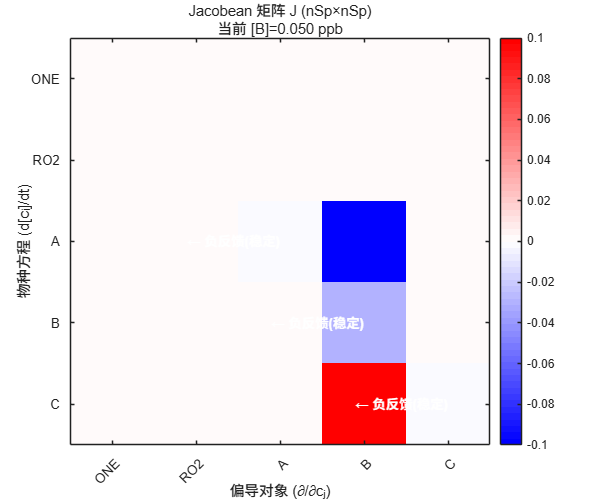

% ---- 可视化 Jacobian ----
figure('Position', [150, 150, 600, 500]);

imagesc(J_full);
colorbar;
colormap(redbluecm);
title(sprintf('Jacobean 矩阵 J (nSp×nSp)\n当前 [B]=%.3f ppb', conc_ppb(4)));
xlabel('偏导对象 (∂/∂cⱼ)');
ylabel('物种方程 (d[cᵢ]/dt)');
set(gca, 'XTick', 1:nSp, 'XTickLabel', Cnames, ...
    'YTick', 1:nSp, 'YTickLabel', Cnames);
xtickangle(45);

% 标注对角线 (自反馈)
hold on;
for i = 1:nSp
    if J_full(i,i) < 0
        text(i, i, '← 负反馈(稳定)', 'HorizontalAlignment', 'right', ...
            'Color', 'w', 'FontWeight', 'bold', 'FontSize', 10);
    elseif J_full(i,i) > 0
        text(i, i, '→ 正反馈(不稳定)', 'HorizontalAlignment', 'left', ...
            'Color', 'k', 'FontWeight', 'bold', 'FontSize', 10);
    end
end

## 步骤 5：调用 ode15s 求解 ODE 系统

% 建立 ODE 函数 (与 F0AM 的 dydt_eval 完全一致)
fprintf('\n\n===== ODE 求解 =====\n');



===== ODE 求解 =====



% 定义 ODE 方程函数
dydt_func = @(t, y) ode_system(t, y, k_values, iG, f_full, nSp);

% 初始条件 (ppb)
y0 = [1; 0; 100; 0.05; 0];  % ONE, RO2, A, B, C

% 时间范围 (1 小时 = 3600 秒)
tspan = [0, 3600];

fprintf('初始条件: [A]=%.1f ppb, [B]=%.3f ppb, [C]=%.1f ppb\n', y0(3), y0(4), y0(5));

初始条件: [A]=100.0 ppb, [B]=0.050 ppb, [C]=0.0 ppb


fprintf('模拟时长: %.0f 秒 (%.1f 小时)\n', tspan(2), tspan(2)/3600);

模拟时长: 3600 秒 (1.0 小时)



% 设置 ODE 选项: 提供 Jacobian (加速!)
fprintf('\n设置 odeset:\n');


设置 odeset:


fprintf('  ✔ Jacobian = 解析 Jacobian 函数\n');

  ✔ Jacobian = 解析 Jacobian 函数


fprintf('  ✔ 使用 ode15s (刚性求解器)\n');

  ✔ 使用 ode15s (刚性求解器)



J_func = @(t, y) jacobian_system(t, y, k_values, iG, f_full, nSp);

options = odeset('Jacobian', J_func);

% 求解
fprintf('\n正在调用 ode15s 求解...\n');


正在调用 ode15s 求解...


tic;
[t, y] = ode15s(dydt_func, tspan, y0, options);
elapsed = toc;
fprintf('完成! 用时 %.3f 秒, %d 个时间步\n', elapsed, length(t));

完成! 用时 0.074 秒, 64 个时间步


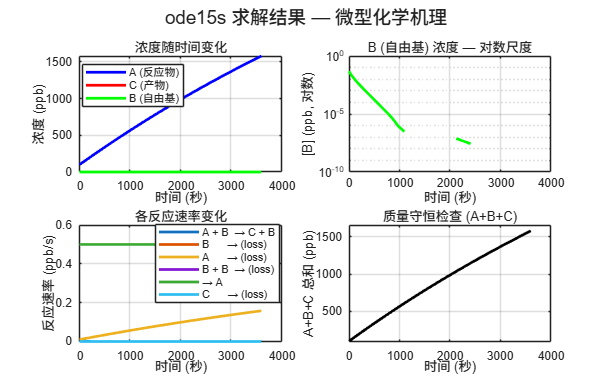


% ---- 绘图: 浓度时间序列 ----
figure('Position', [200, 200, 800, 500]);

subplot(2,2,1);
plot(t, y(:,3), 'b-', 'LineWidth', 2); hold on;
plot(t, y(:,5), 'r-', 'LineWidth', 2);
plot(t, y(:,4), 'g-', 'LineWidth', 2);
xlabel('时间 (秒)'); ylabel('浓度 (ppb)');
legend('A (反应物)', 'C (产物)', 'B (自由基)', 'Location', 'best');
title('浓度随时间变化');
grid on; box on;

subplot(2,2,2);
semilogy(t, y(:,4), 'g-', 'LineWidth', 2);
xlabel('时间 (秒)'); ylabel('[B] (ppb, 对数)');
title('B (自由基) 浓度 — 对数尺度');
grid on; box on;

% 反应速率随时间变化
subplot(2,2,3);
G_all = zeros(length(t), nRx);
for j = 1:nRx
    G_all(:,j) = y(:, iG(j,1)) .* y(:, iG(j,2)) .* y(:, iG(j,3));
end
rates_all = k_values(:)' .* G_all;
plot(t, rates_all, 'LineWidth', 2);
xlabel('时间 (秒)'); ylabel('反应速率 (ppb/s)');
legend(Rnames, 'Location', 'best', 'FontSize', 8);
title('各反应速率变化');
grid on; box on;

% 浓度和 (质量守恒检查)
subplot(2,2,4);
conc_sum = sum(y(:,3:5), 2);
plot(t, conc_sum, 'k-', 'LineWidth', 2);
xlabel('时间 (秒)'); ylabel('A+B+C 总和 (ppb)');
title('质量守恒检查 (A+B+C)');
grid on; box on;
ylim([min(conc_sum)*0.95, max(conc_sum)*1.05]);

sgtitle('ode15s 求解结果 — 微型化学机理', 'FontSize', 14);

## 步骤 6：Jacobian 随时间演化 — 热力图动画

fprintf('\n\n===== Jacobian 热力图动画 =====\n');



===== Jacobian 热力图动画 =====


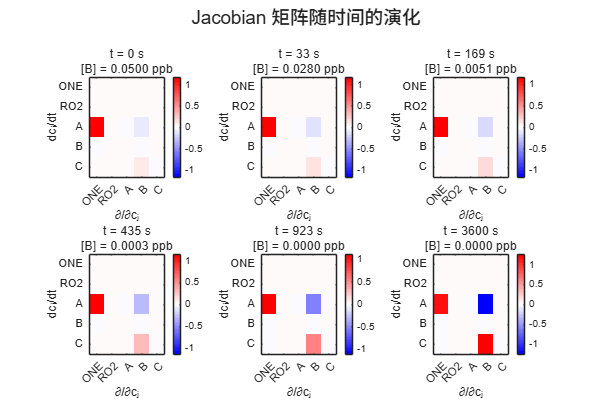


% 选取几个时间点展示 Jacobian 如何随浓度变化
n_frames = 6;
idx_frames = round(linspace(1, length(t), n_frames));
time_points = t(idx_frames);

figure('Position', [250, 250, 900, 600]);

for k = 1:n_frames
    yy = y(idx_frames(k), :)';
    J_now = f_full' * drdy_at_conc(yy, k_values, iG, nSp);
    
    subplot(2, 3, k);
    imagesc(J_now, [-max(abs(J_now(:)))*0.8, max(abs(J_now(:)))*0.8]);
    colormap(redbluecm);
    colorbar;
    title(sprintf('t = %.0f s\n[B] = %.4f ppb', t(idx_frames(k)), yy(4)));
    xlabel('∂/∂cⱼ'); ylabel('dcᵢ/dt');
    set(gca, 'XTick', 1:nSp, 'XTickLabel', Cnames, ...
        'YTick', 1:nSp, 'YTickLabel', Cnames);
    xtickangle(45);
end
sgtitle('Jacobian 矩阵随时间的演化', 'FontSize', 14);

## 步骤 7：完整 F0AM 风格求解 (含 RO2)

% 在 F0AM 中，RO2 = 所有有机过氧自由基之和
% 这里模拟 RO2 由 A 氧化产生
%
% 真正 F0AM: RO2 在每步 dydt 中更新:
%   conc(:,2) = sum(conc(:, iRO2_list), 2);
%
% 这里我们展示完整流程: A+B → B+C 生成的 C 的一部分是 RO2
% 简化: 设 RO2 = C × 0.3 (30% 产物是自由基)

fprintf('\n\n===== 完整 F0AM 流程模拟 =====\n');



===== 完整 F0AM 流程模拟 =====


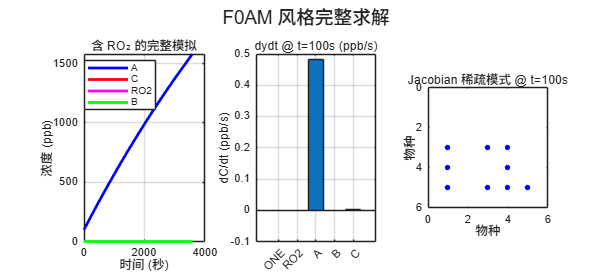


% 重新定义 ODE 函数: 包含 RO2 更新
dydt_f0am = @(t, y) ode_system_f0am(t, y, k_values, iG, f_full, nSp, 3);

% 初始条件 (包含 RO2)
y0_f0am = [1; 0.01; 100; 0.05; 0];  % RO2 初始 0.01 ppb

% 求解
options2 = odeset('Jacobian', @(t,y) jacobian_system_f0am(t,y,k_values,iG,f_full,nSp,3));
[t2, y2] = ode15s(dydt_f0am, [0, 3600], y0_f0am, options2);

% 绘图: 对比有无 RO2 的差异
figure('Position', [300, 300, 900, 400]);

subplot(1,3,1);
plot(t2, y2(:,3), 'b-', 'LineWidth', 2); hold on;
plot(t2, y2(:,5), 'r-', 'LineWidth', 2);
plot(t2, y2(:,2), 'm-', 'LineWidth', 2);
plot(t2, y2(:,4), 'g-', 'LineWidth', 2);
xlabel('时间 (秒)'); ylabel('浓度 (ppb)');
legend('A', 'C', 'RO2', 'B', 'Location', 'best');
title('含 RO₂ 的完整模拟');
grid on; box on;

subplot(1,3,2);
% dydt 各组分可视化 (在 t=100s 时)
[~, idx_t] = min(abs(t2-100));
y_sample = y2(idx_t,:)';
dydt_sample = dydt_f0am(t2(idx_t), y_sample);
bar(dydt_sample);
set(gca, 'XTick', 1:nSp, 'XTickLabel', Cnames);
title(sprintf('dydt @ t=100s (ppb/s)'));
ylabel('dC/dt (ppb/s)');
grid on; box on;

subplot(1,3,3);
spy(f_full' * drdy_at_conc(y_sample, k_values, iG, nSp), 'b', 12);
title(sprintf('Jacobian 稀疏模式 @ t=100s'));
xlabel('物种'); ylabel('物种');

sgtitle('F0AM 风格完整求解', 'FontSize', 14);

## 总结

fprintf('\n\n===== 总结 =====\n');



===== 总结 =====


fprintf('F0AM ODE 求解的核心步骤:\n\n');

F0AM ODE 求解的核心步骤:



fprintf('  ① 化学机制 → 稀疏矩阵 f (nRx × nSp)\n');

  ① 化学机制 → 稀疏矩阵 f (nRx × nSp)


fprintf('  ② iG 记录每个反应的 1~3 个反应物索引\n');

  ② iG 记录每个反应的 1~3 个反应物索引


fprintf('  ③ 每步 ODE 求导:\n');

  ③ 每步 ODE 求导:


fprintf('       G = conc(iG₁) .* conc(iG₂) .* conc(iG₃)\n');

       G = conc(iG₁) .* conc(iG₂) .* conc(iG₃)


fprintf('       rates = k .* G\n');

       rates = k .* G


fprintf('       dydt = rates * f    ← 一行代码!\n');

       dydt = rates * f    ← 一行代码!


fprintf('  ④ 解析 Jacobian: J = f^T · DrDy\n');

  ④ 解析 Jacobian: J = f^T · DrDy


fprintf('  ⑤ ode15s 利用 J 高速求解\n');

  ⑤ ode15s 利用 J 高速求解


fprintf('  ⑥ 后处理: ppb 转换 + 速率分析\n');

  ⑥ 后处理: ppb 转换 + 速率分析


fprintf('\n关键: 稀疏矩阵让 20000 反应 × 7000 物种\n');


关键: 稀疏矩阵让 20000 反应 × 7000 物种


fprintf('      的矩阵乘法在毫秒级完成!\n');

      的矩阵乘法在毫秒级完成!


## ========== 辅助函数 ==========

function dydt = ode_system(~, y, k, iG, f, nSp)
    % ODE 导数函数 (与 F0AM dydt_eval 原理一致)
    y = y(:);
    
    % 计算反应物浓度积
    G = y(iG(:,1)) .* y(iG(:,2)) .* y(iG(:,3));
    
    % 反应速率
    rates = k(:) .* G;
    
    % 核心: dydt = rates · f
    dydt = rates' * f;
    dydt = dydt(:);
    
    % ONE 不动, RO2 暂为 0
    dydt(1) = 0;
    dydt(2) = 0;
end

function J = jacobian_system(~, y, k, iG, f, nSp)
    % 解析 Jacobian (与 F0AM Jac_eval 原理一致)
    y = y(:);
    
    % 计算 ∂rates/∂conc
    DrDy = drdy_at_conc(y, k, iG, nSp);
    
    % J = f^T · DrDy
    J = f' * DrDy;
    
    % ONE 和 RO2 的行置零
    J(1,:) = 0;
    J(2,:) = 0;
end

function dydt = ode_system_f0am(~, y, k, iG, f, nSp, iRO2_species)
    % 含 RO2 更新的 ODE 导数函数
    y = y(:);
    
    % 更新 RO2 = 指定物种的浓度
    y(2) = y(iRO2_species) * 0.3;  % 30% 产物作为 RO2
    
    % 计算反应物浓度积
    G = y(iG(:,1)) .* y(iG(:,2)) .* y(iG(:,3));
    
    % 反应速率
    rates = k(:) .* G;
    
    % 核心: dydt = rates · f
    dydt = rates' * f;
    dydt = dydt(:);
    
    dydt(1) = 0;  % ONE 不动
end

function J = jacobian_system_f0am(~, y, k, iG, f, nSp, iRO2_species)
    % 含 RO2 更新的 Jacobian
    y = y(:);
    y(2) = y(iRO2_species) * 0.3;
    
    DrDy = drdy_at_conc(y, k, iG, nSp);
    J = f' * DrDy;
    J(1,:) = 0;
    J(2,:) = 0;
end

function DrDy = drdy_at_conc(y, k, iG, nSp)
    % 计算 ∂rates/∂conc 在当前浓度 y 下的值
    nRx = length(k);
    DrDy = zeros(nRx, nSp);
    
    for i = 1:nRx
        % 对每个反应物的偏导
        DrDy(i, iG(i,1)) = k(i) * y(iG(i,2)) * y(iG(i,3));
        DrDy(i, iG(i,2)) = DrDy(i, iG(i,2)) + k(i) * y(iG(i,1)) * y(iG(i,3));
        DrDy(i, iG(i,3)) = DrDy(i, iG(i,3)) + k(i) * y(iG(i,1)) * y(iG(i,2));
        
        % 自反应修正
        if (iG(i,1) == iG(i,2) && iG(i,1) ~= 1)
            DrDy(i, iG(i,1)) = 2 * k(i) * y(iG(i,1));
        end
        if (iG(i,1) == iG(i,3) && iG(i,1) ~= 1)
            DrDy(i, iG(i,1)) = 2 * k(i) * y(iG(i,1));
        end
        if (iG(i,3) == iG(i,2) && iG(i,3) ~= 1)
            DrDy(i, iG(i,3)) = 2 * k(i) * y(iG(i,3));
        end
    end
end

function cmap = redbluecm
    % 红蓝分色图 (正=红, 负=蓝, 0=白)
    n = 64;
    cmap = zeros(n, 3);
    for i = 1:n
        t = (i-1)/(n-1);
        if t < 0.5
            % 蓝到白
            cmap(i,:) = [t*2, t*2, 1];
        else
            % 白到红
            cmap(i,:) = [1, (1-t)*2, (1-t)*2];
        end
    end
end